%% useful_tools
sigma_0 = pauli_matric(0); sigma_x = pauli_matric(1); sigma_y = pauli_matric(2); sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0); tau_x   = pauli_matric(1); tau_y   = pauli_matric(2); tau_z   = pauli_matric(3);

**变量名不能含有xyz这样的字符**

syms Delta m v lambda u1 u2;
syms k_x k_y k_z c real ;
H_2D = HK(4,2);

% the coeffs is not allowed use x y z

H_2D = H_2D ...
    + Term( -Delta + m*k_x^2+m*k_y^2,sigma_z*tau_0)...
    + Term( v*k_x,                   sigma_x*tau_x)...
    + Term( v*k_y,                   sigma_x*tau_y)...
    + Term( lambda*(k_x^2-k_y^2),    sigma_z*tau_x)...
    + Term( 2*lambda*(k_x * k_y),    sigma_z*tau_y)...
    ;

Setting 3/3 term into HK ...


Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


Setting 2/2 term into HK ...


Setting 1/1 term into HK ...


H_3D = H_2D ...
    + Trig( u1*(cos(k_z) )       ,    sigma_z*tau_0)...
    + Trig( u2*(sin(k_z))          ,    sigma_z*tau_0)...
    ;
% H_3D = H_3D < 'POSCAR';
H_3D = H_3D.input_Rm();
H_3D = H_3D < 'KPOINTS';

direct plus test

H_Direct = HK(4,2);
H_Direct = H_Direct + H_2D.sym();

Setting 3/3 term into HK ...
Setting 3/3 term into HK ...
Setting 2/2 term into HK ...
Setting 3/3 term into HK ...
Setting 3/3 term into HK ...
Setting 2/2 term into HK ...
Setting 2/2 term into HK ...
Setting 3/3 term into HK ...
Setting 3/3 term into HK ...
Setting 2/2 term into HK ...
Setting 3/3 term into HK ...
Setting 3/3 term into HK ...


% para

b = 1.424e-10;
h_bar =6.582119514e-16; %eV⋅s
v = 7e5 * h_bar /b  ; % m/s
Delta = 0.213 ; % eV
lambda = 0.230; % eV
u1 = 0.26      ;
u2 = 0.23      ;
m = 0.233     ;
c = 3.3  ;
v = 0;

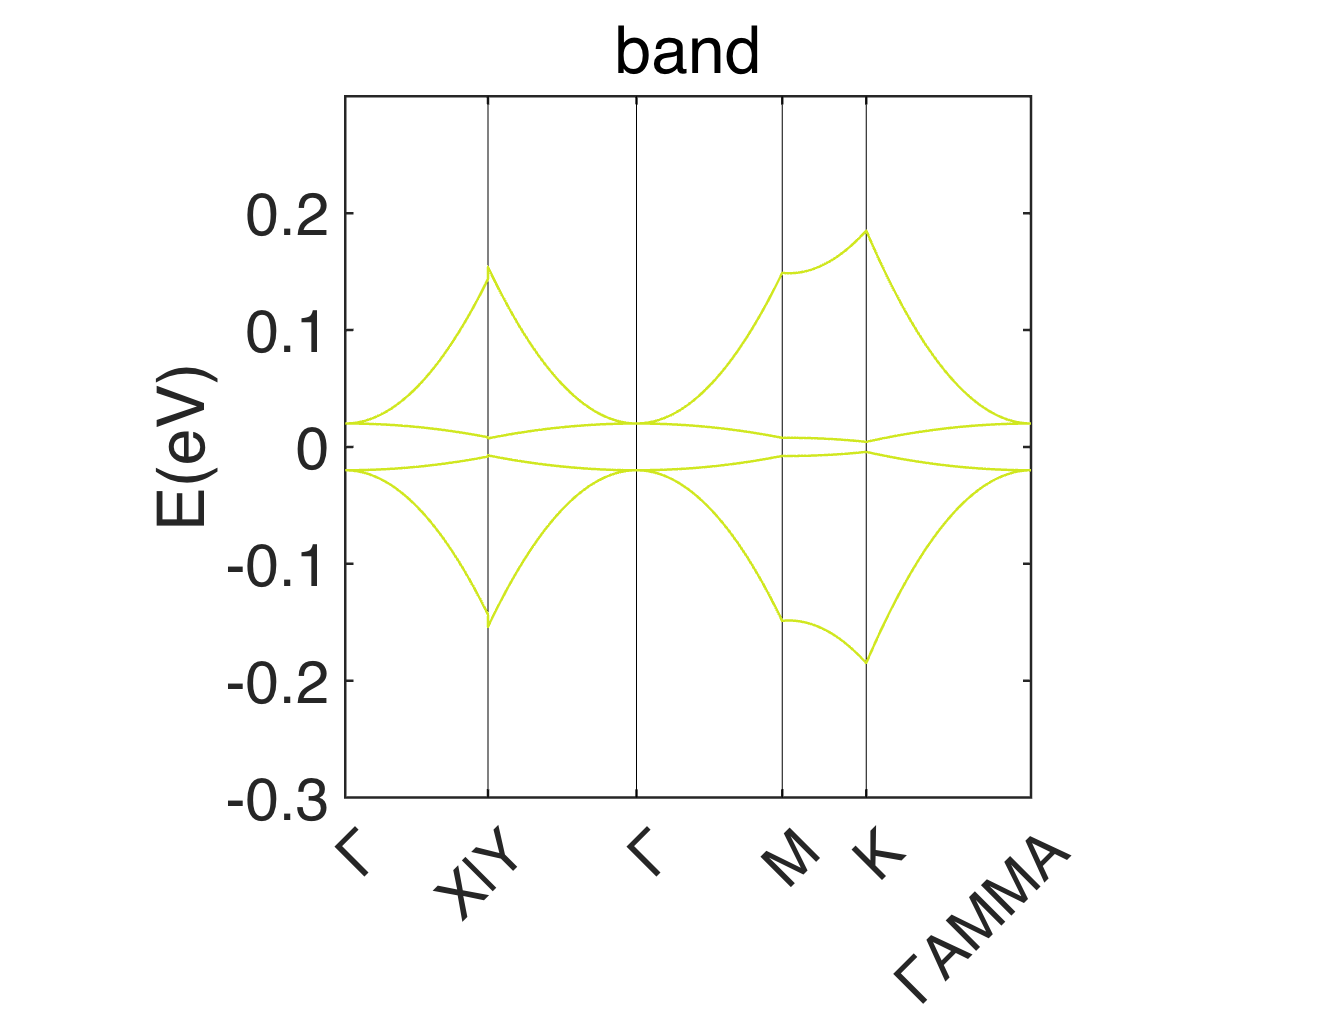

%v =0;
u1 =0.233;
u2 =0.23;
m =0.19;
Delta =0.213;
tolerance = 0.037;
kmesh = [5,23,5];
H_3Dn = H_3D.Subsall();
%
EIGENCAR = H_3Dn.EIGENCAR_gen();
bandplot(EIGENCAR,[-0.3,0.3]);


%[k_list_cart,klist_f,~]=H_3Dn.findnodes(kmesh,2,tolerance); 